## Problem 2

txtfile = 'exoplanets.txt';
exoplanets = readtable(txtfile);

**a) First exoplanet discovered**

year = table2array(exoplanets(:, 9));
firstYear = min(year);
row = exoplanets.Year == 1988;
firstExoplanet = string(exoplanets{row, 1})

firstExoplanet = "PSR B1957+20 b"

yearDiscovered = firstYear

yearDiscovered =         1988


method = string(exoplanets{row, 8})

method = "pulsar"

[pT,pg,v] = planet(exoplanets.Mass(row),exoplanets.Radius(row),exoplanets.Smass(row),exoplanets.Orbit(row), "AU");
periodOfOrbit = pT

periodOfOrbit =       0.30992


surfaceGravity = pg

surfaceGravity =         588.2


orbitalVelocity = v

orbitalVelocity =        351.97


**b) Habitable planets**

numHabitablePlanets = sum(exoplanets.Habitable)

numHabitablePlanets =     54


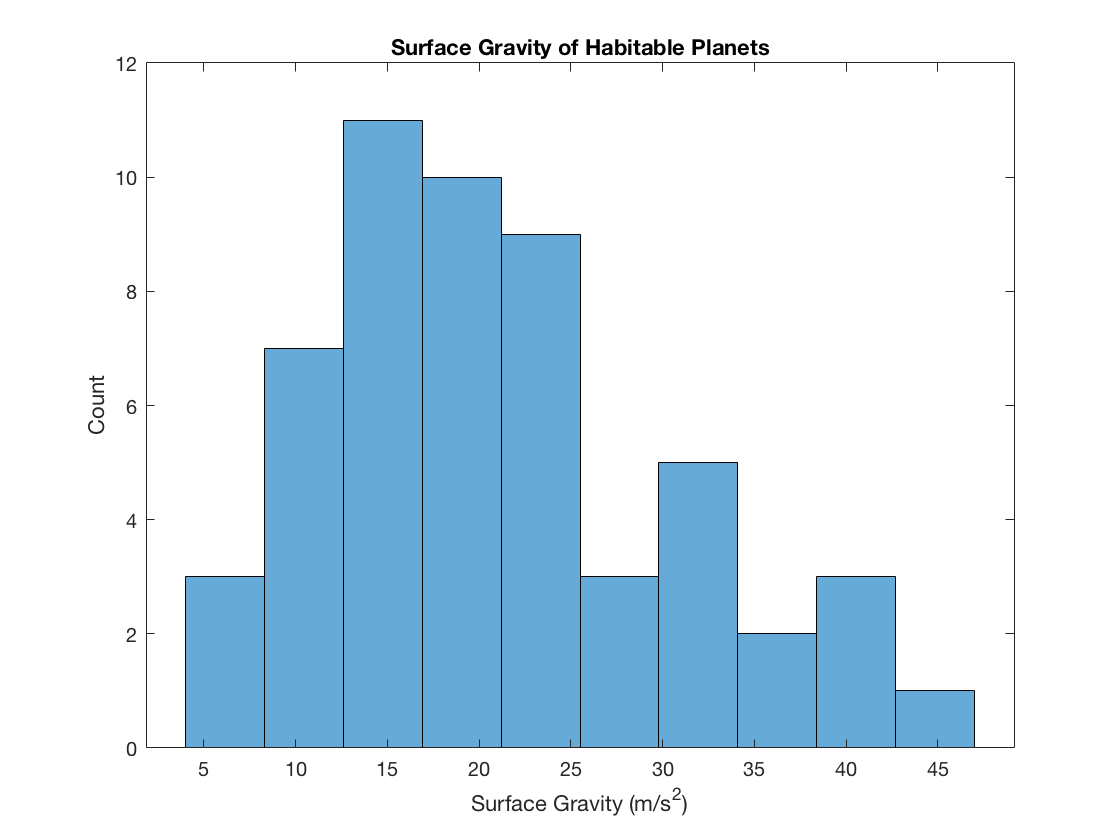

habPlanMass = exoplanets.Mass(exoplanets.Habitable == 1); 
habPlanRad = exoplanets.Radius(exoplanets.Habitable == 1);
habPlanSmass = exoplanets.Smass(exoplanets.Habitable == 1);
habPlanOrb = exoplanets.Orbit(exoplanets.Habitable == 1);
[pTplot,pgplot,vplot] = planet(habPlanMass,habPlanRad,habPlanSmass,habPlanOrb, "AU");

histogram(pgplot, 10)
title("Surface Gravity of Habitable Planets")
xlabel("Surface Gravity (m/s^2)")
ylabel("Count")

Most of the habitable planets have a much higher surface gravity that Earth.

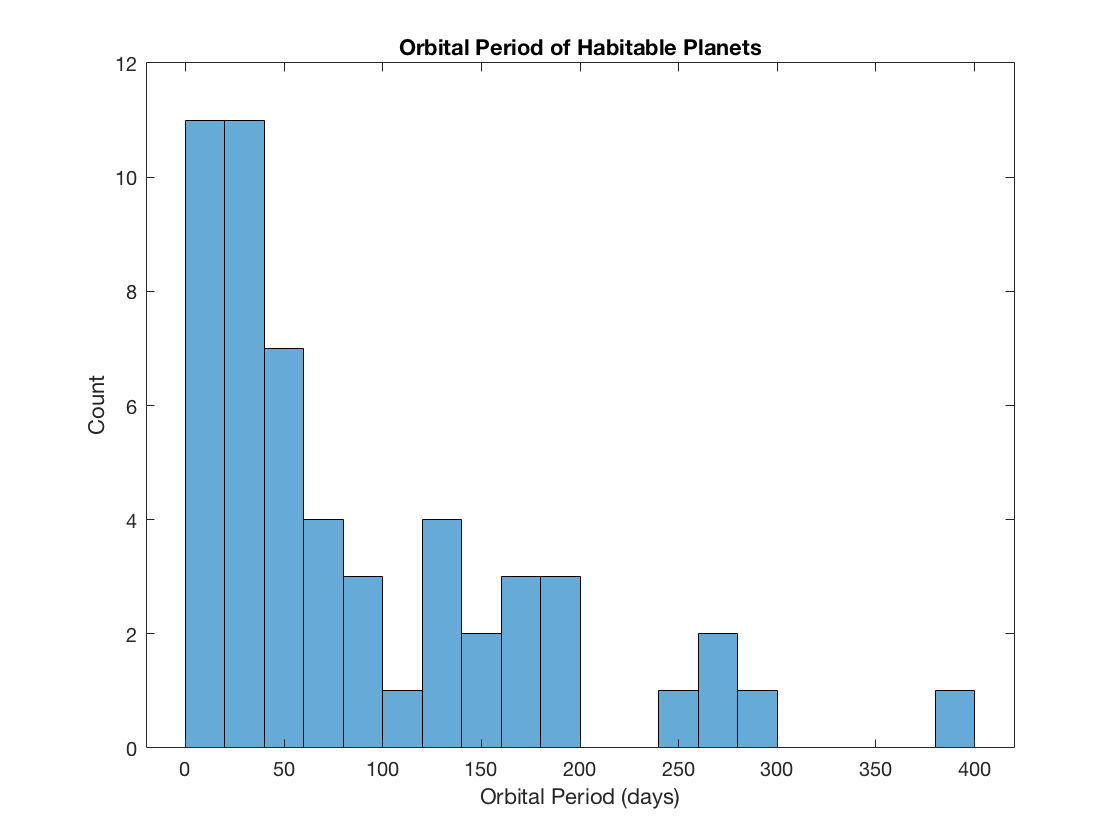

histogram(pTplot, 20)
title("Orbital Period of Habitable Planets")
xlabel("Orbital Period (days)")
ylabel("Count")

Most of the habitable planets have a shorter orbital period than the Earth.

**c) Star mass and orbital radius**

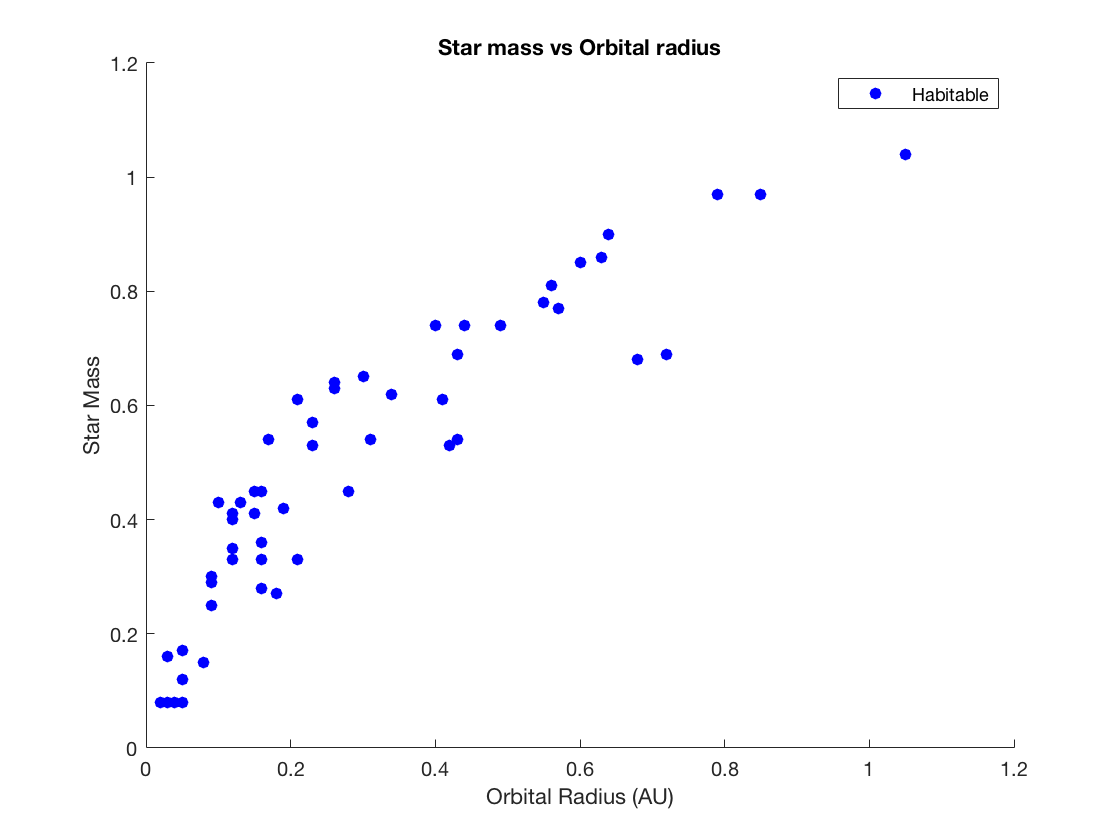

haborbrad = (exoplanets.Orbit(((exoplanets.Orbit < 6) == 1) & (exoplanets.Habitable == 1)));
habsmass = (exoplanets.Smass(((exoplanets.Orbit < 6) == 1) & (exoplanets.Habitable == 1)));

unhaborbrad = (exoplanets.Orbit((exoplanets.Orbit < 6) == 1 & (exoplanets.Habitable == 0)));
unhabsmass = (exoplanets.Smass((exoplanets.Orbit < 6) == 1 & (exoplanets.Habitable == 0)));

%only habitable
scatter(haborbrad,habsmass, 'filled', 'b')
title('Star mass vs Orbital radius')
xlabel('Orbital Radius (AU)')
ylabel('Star Mass')
legend("Habitable")

As the mass of the planet's star gets larger, the orbital radius of the planet must also be larger for the planet to be habitable.

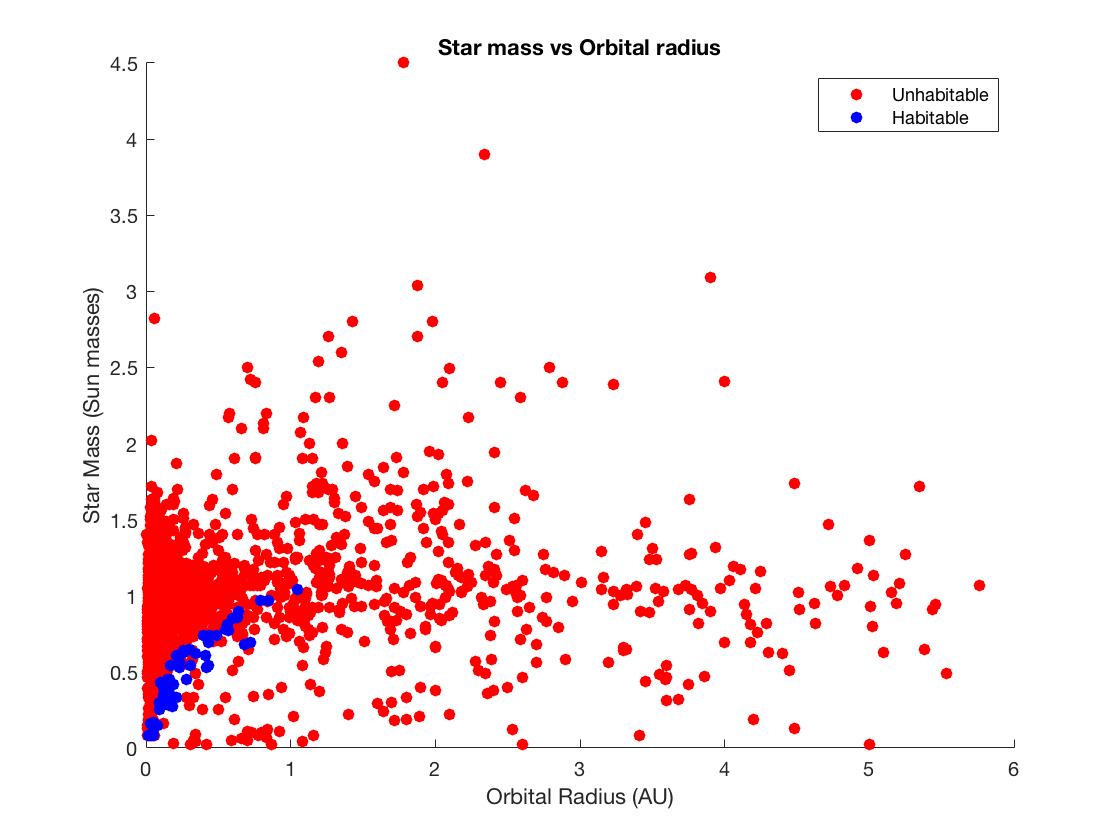

%habitable and unhabitale
scatter(unhaborbrad,unhabsmass, 'filled', 'r')
hold on
scatter(haborbrad,habsmass, 'filled', 'b')
title('Star mass vs Orbital radius')
xlabel('Orbital Radius (AU)')
ylabel('Star Mass (Sun masses)')
legend("Unhabitable", "Habitable")

Most of the unhabitable planets seem to be too close to their star, while there are also some unhabitable planets that are too far away from their star and also fall outside of the habitable zone.

**d) Method of detection**

[C,ia,ic] = unique(exoplanets.Method);

a_counts = accumarray(ic,1);
C = cell2table(C);
a_counts = array2table(a_counts);
method_counts = [C, a_counts];
maxmethod = max(method_counts.a_counts);
mcmethod = method_counts((method_counts.a_counts == maxmethod),1);
mostCommonMethod = string(mcmethod{1, 1})

mostCommonMethod = "transit"


total = sum(method_counts.a_counts);
percent = (maxmethod/total)*100

percent =        48.768
